clear all

data=importdata("Triangle_Large_003_C1_vector_table_50grid_50window_gaussian.csv");

X=data.data(:,1);

Y=data.data(:,2);

dx=data.data(:,4);

dy=data.data(:,5);

Ori=data.data(:,6); %Orientation (in degrees angle)

En=data.data(:,8); %Energy 


theta1=reshape(Ori,146,142); %x=235,y=136 for 003, x=241,y=142 for 004,  x=248, y=146 for 006.
%for 45A45A90 we have: x=146, y=142 for 003 
theta1=transpose(theta1);

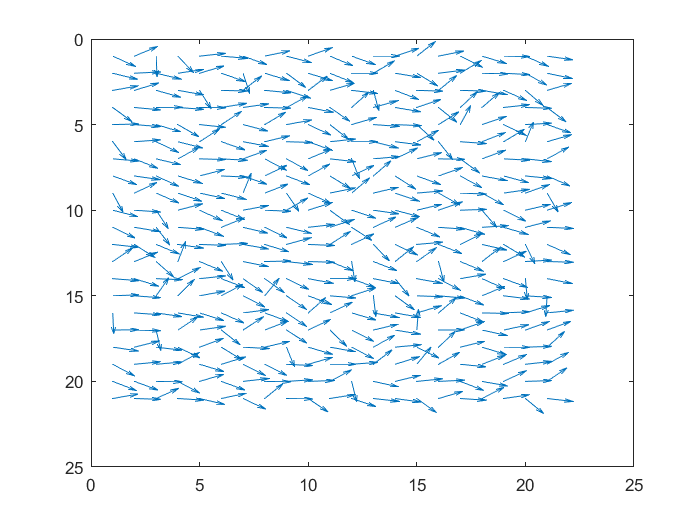

%theta2=theta1(80:100,1:21)/180*pi;
%theta2=degree_state/180*pi;
theta2=S;

%theta2=theta2(1:21,40:60);

%theta2=rot90(theta2,3)+1*pi/2; %if i want it to go from the left hand side
%to the upper side of the matrix i choose 3 when i do rot90 and then i add
%pi/2 which means 90deg to the angle. If the arrows point the other way i
%subtract 90 degree. this way i can calculate alpha, although K1 and K3
%will be the same in all instances.

figure(1); quiver(cos(theta2),sin(theta2))
set (gca,'Ydir','reverse')


phi=transpose(theta2);
phi=reshape(phi,1,[]);
phi=transpose(phi);


H=size(theta2,1);
L=size(theta2,2);

E=zeros(H,L);

%load('Simulation_data.mat');
%SimData;

[Matrix, M4] = Matrixcalculation(H);

% eta1=7*randn(H,H)/180*pi;
% eta2=transpose(eta1);
% eta2=reshape(eta2,1,[]);
% eta2=transpose(eta2);

cd('cube-main')
cd('path_to_cube')
obs=phi;
N=H*H;
model=struct('genu',@(obs) rand(1,2));
model.u2theta=@(u,obs) [-10*log(u(1)),-0.1*log(u(2))+1E-5]; %theta(1)=K and theta(2)=alpha
model.logl=@(phi,theta) logl(Matrix, M4, theta(2), theta(1), obs, N);
model.labels={'K','alpha'};
results=cube_main(obs,model);

After 500 processed samples: Zrat = 367
After 1000 processed samples: Zrat = 0.58
After 1500 processed samples: Zrat = 0.0531
After 2000 processed samples: Zrat = 0.005
Generated 2529 samples for Model 1.
CUBE is done.
Elapsed time is 92.097235 seconds.


cd('cube-main')
cd('path_to_cube')
obs=phi;
N=H*H;
model=struct('genu',@(obs) rand(1,3));
model.u2theta=@(u,obs) [-30*log(u(1)),-3*log(u(2))+1E-5, -1*log(u(3))]; %theta(1)=K and theta(2)=alpha theta(3)=spredning af sigma
model.logl=@(phi,theta) logl2(Matrix, M4, theta(2), theta(1), obs, theta(3), N);
model.labels={'K','alpha', 'SD noise'};
results2=cube_main(obs,model);

After 500 processed samples: Zrat = 1.47e+04
After 1000 processed samples: Zrat = 0.361
After 1500 processed samples: Zrat = 0.0237
After 2000 processed samples: Zrat = 0.00206
Generated 2353 samples for Model 1.
CUBE is done.
Elapsed time is 503.953745 seconds.


function b1 = logl(Matrix, M4, alfa, k, obs, N)

    Mat = Matrix + M4 * alfa;

    M = chol(Mat, "lower");
 
    y = M' * obs;

    b1 = sum(log(diag(M))) - N * 0.5 * log(2 * pi / k) - (k / 2) * (y' * y);
end




function [Matrix, M4] = Matrixcalculation(H)
Matrix1=-1*ones(H*H,H*H);
Matrix2=3*ones(H*H,H*H);
M2=zeros(H*H,H*H);
M3=zeros(H*H,H*H);
M6=zeros(H*H,H*H);
for j=1:2
k=1;
if j>1
M2=Matrix;
end
    if j==1  % code for odd
for i=1:2
if i>1
M2=Matrix;
end
Matrix=diag(diag(Matrix1,k-H*(j-1)),k-H*(j-1))+1/2*diag(diag(Matrix2,H*(j-1)),H*(j-1));

Matrix=M2+Matrix;
k=k-2;
end
    end
    
if j==2
M2=Matrix;

Matrix=diag(diag(Matrix1,(1)-(H*(j-1)+1)),(1)-(H*(j-1)+1))+diag(diag(Matrix1,k+(H*(j-1)-1)),k+(H*(j-1)-1));
Matrix=M2+Matrix;
end

end

M4=zeros(H*H,H*H);
for i=1:H
    
        M3((i-1)*H+1,(i-1)*H+1)=Matrix((i-1)*H+1,(i-1)*H+1)-4;%alfa
        M6(i*H,i*H)=Matrix(i*H,i*H)-4;
        
        M4(i,i)=1;
        
end

Matrix=Matrix+M3+M6;


for i=1+H:H*H-H
    
    Matrix(i,i)=Matrix(i,i)+1;
    
end

for i=1:H-1
    Matrix(i*H+1,i*H)=0;
    Matrix(i*H,i*H+1)=0;
end

end




function b1 = logl2(Matrix, M4, alfa, k, obs, spredning, N)
    Mat = k * Matrix + k * M4 * alfa;
    
    b2 = inv(Mat);  % Use backslash instead of inv
    
    cov = b2 + (spredning)^2 * eye(size(b2)); %adds standard deviation of noise to the diagonal
    
    M1 = chol(cov, "lower");
    
    %M = inv(M1);
    
    y = linsolve(M1',obs, struct('LT', true)); %to solve y=inv(M1')*obs' => M1'*y=obs

    b1 = -sum(log(diag(M1))) - N * 0.5 * log(2 * pi) -  (1 / 2) * (y' * y);
end
